# Relatório de Atividade - Estimação de parâmetros

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Estimação e Identificação de Sistemas 21.2*

*16 de agosto de 2021*

Esse documento tem por objetivo descrever a identificação de modelos pelo método dos mínimos quadrados. Esse algoritmo determina uma estimação dos parâmetros de um modelo e é adequado para ***processos não-lineares ou variantes no tempo***. 

## Fundamentação teórica

Com base em dados coletados, é possível identificar um modelo cujo comportamento é semelhante à um planta qualquer observada. Entretanto, é importante destacar que esse modelo deve ser anteriormente validado, uma vez que os dados coletados podem representar apenas um ponto de operação específico. Além disso, é importante garantir que os dados coletados sejam representativos, isto é, que o experimento realizado explore corretamente os valores reais de entrada da planta. 

Nesse documento, serão identificados sistemas dinâmicos, isto é, plantas cuja saída atual dependem dos valores de entrada atual e de entrada e saída anteriores. Dessa forma, a saída $y(t)$ do processo pode ser representada como:


$$y(t) +a_1y(t-1)+...+a_ny(t-1) = b_1u(t-1)+...+b_mu(t-m)$$


O tempo de amostragem é considerado unitário, e os sistemas analisados serão sistemas discretos. A saída estimada do processo $\hat{y}(t)$ pode ser representado compactamente por:


$$\hat{y}(t)= - a_1y(t-1) - ... - a_ny(t-n) + b_1u(t-1)+...+b_mu(t-m) = \varphi^T(t)\theta$$


para $\varphi(t) = [-y(t-1)\; ...-y(t-n)\ u(t-1)\; ...\; u(t-m)]^T$ e $\theta = [a_1\; ...\; a_n\ b_1\; ...\; b_m]^T$. É evidente que o modelo sugerido para a identificação é linear. Dessa forma, a escolha de $\theta$ para alcançar a saída $y(t)$ é calculada conforme uma função de custo $V(\theta,t)$, que, para o método dos mínimos quadrados, é definida como o erro quadrático médio do valor real medido e o estimado em $N$ amostras coletadas:


$$V(\theta,t)=\frac{1}{N}\sum_{t=1}^N \big[y(t)-\hat{y}(t)\big]^2 = \frac{1}{N}\sum_{k=1}^T \big[y(t)-\varphi^T(t)\theta\big]^2$$


Para encontrar $\hat{\theta}=\arg \min_\theta V(\theta,t)$, encontra-se $\hat{\theta}$ tal que $\partial V(\hat{\theta},t)/\partial\theta=0$:


$$\sum_{t=1}^N \varphi(t)\big[y(t)-\varphi^T(t)\hat{\theta}\big] =0 \rightarrow\sum_{t=1}^N  \varphi(t)y(t) = \sum_{t=1}^N \varphi(t)\varphi^T(t)\hat{\theta}$$



$$\therefore \hat{\theta} = \Big[\sum_{t=1}^N\varphi(t)\varphi^T(t)\Big]^{-1}\sum_{t=1}^N\varphi(t)y(t)  = P(t) \sum_{t=1}^N\varphi(t)y(t)$$


Logo, é evidente que $P(t)$ deve ser positiva definida.  Se considerarmos que há um ruído branco de média nula $e(t)$ na saída $y(t)$, é possível considerar esse erro na modelagem ao reescrever a equação de estimação como:


$$\hat{y}(t)= \varphi^T(t)\theta_0+e(t)
$$


Logo, encontra-se que:


$$\hat{\theta}_0 = P(t) \sum_{t=1}^N\varphi(t)\big[y(t)+e(t)\big]$$


Sendo assim, o erro entre a estimativa $\hat{\theta}$ não considerando o erro na modelagem e $\hat{\theta}_0$ considerando o erro na modelagem é dado por:


$$\tilde{\theta}=\hat{\theta}-\hat{\theta}_0 = P(t)\sum_{t=1}^N\varphi(t)e(t)$$


A esperança desse erro é então dado por:


$$E(\tilde{\theta}) = P(t)\sum_{t=1}^N\varphi(t)E\big(e(t)\big) = 0$$


Logo, é possível concluir que a estimativa por mínimos quadrados para modelos com ruído branco na medição não possui viés.

## Desenvolvimento, resultados e discussão

Com o intuito de verificar o processo de identificação de uma planta desconhecida pelo método dos mínimos quadrados, serão simulados dois modelos discretos $\delta_1$ e $\delta_2$ . Ambos equacionamentos consideram o erro com distribuição normal $e(t)$ na modelagem. A função de transferência para $\delta_1$ e $\delta_2$ são, respectivamente:


$$\delta_1 : Y= \frac{q^{-1}}{1-0.8q^{-1}}U+ \frac{q^{-1}}{1-0.8q^{-1}}E$$



$$\delta_2 : Y= \frac{q^{-1}}{1-0.8q^{-1}}U+ E$$


para $u(t)$ e $e(t)$ a entrada e erro, respectivamente. Ao transformar as funções de transferência dos sistemas $\delta_1$ e $\delta_2$ para o domínio do tempo, obtém-se:


$$\delta_1 : y(t) = 0.8y(t-1)+u(t-1)+e(t-1)$$



$$\delta_2 : y(t) = 0.8y(t-1)+u(t-1)+e(t)-0.8e(t-1)$$


Para os experimentos realizados, foi considerado que tanto $u(t)$ como $e(t)$ são variáveis aleatórias de distribuição normal com média nula e variância unitária, ou seja, $u \sim N(0,1)$ e $e \sim N(0,1)$. Para $N=200$ amostras, é possível gerar os sinais de entrada $u(t)$ e $e(t)$ e de saída $y_1(t)$ e $y_2(t)$para cada dos modelos $\delta_1$ e $\delta_2$ conforme ilustrado na Figura 1.

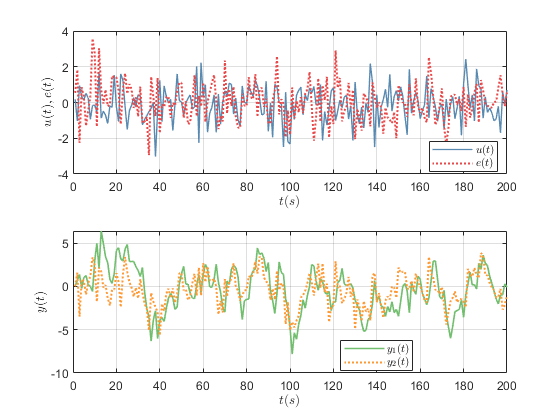

inputGen

**Figura 1:** Sinais de entrada $u(t)$ e $e(t)$ e de saída $y_1(t)$ e $y_2(t)$dos modelos $\delta_1$ e $\delta_2$, respectivamente.

Em seguida, os parâmetros da função de transferência $H(q)=Y(q)/U(q)$ foram estimados utilizando o método dos mínimos quadrados descrito na seção anterior. Para os modelos $\delta_1$ e $\delta_2$, considerou-se um sistema parametrizado por duas constantes $a$ e $b$ conforme a função de transferência $H(q^{-1})$:


$$H(q^{-1})= \frac{bq^{-1}}{1+aq^{-1}}$$


 Os parâmetros $\hat{a}$ e $\hat{b}$ estimados em função do tempo estão ilustrados na Figura 2. 

estimateGen

**Figura 2:** Parâmetros estimados  $\hat{a}$ e $\hat{b}$ para os modelos simulados $\delta_1$ e $\delta_2$, respectivamente.

Observando a Figura 2, é evidente que os parâmetros estimados convergem para o valor real apenas para o modelo $\delta_1$.

Além disso, é claro que $\delta_1$ depende unicamente dos valores de erro $e(t-1)$ no instante anterior, enquanto o modelo $\delta_2$ é influenciado pelo termo da amostra atual $e(t)$ e anterior $e(t-1)$. A covariância do sinal $z(t) = e(t)+e(t-1)$ é dada por:


$$\mathrm{Cov}\big[z(t),z(t-j)\big] = \mathrm{Cov}\big[e(t),e(t-j)\big]+\mathrm{Cov}\big[e(t-1),e(t-1-j)\big] + \mathrm{Cov}\big[e(t-1),e(t-j)\big]+\mathrm{Cov}\big[e(t),e(t-1-j)\big]$$


Como $e(t)$ e $e(t-1)$ possuem distribuição normal, é evidente que $\mathrm{Cov}\big[e(t),e(t-j)\big]=\mathrm{Cov}\big[e(t-1),e(t-1-j)\big]=0$ para $j\neq0$. Logo, tem-se que para $j\neq0$:


$$\mathrm{Cov}\big[z(t),z(t-j)\big] =  \mathrm{Cov}\big[e(t-1),e(t-j)\big]+\mathrm{Cov}\big[e(t),e(t-1-j)\big]$$


Para $z(t)$ ser um ruído gaussiano, a covariância desse sinal deve ser nula para qualquer $j\neq0$. Entretanto, para $j=1$, a expressão resulta em:


$$\mathrm{Cov}\big[z(t),z(t-1)\big] =  \mathrm{Cov}\big[e(t-1),e(t-1)\big]+\mathrm{Cov}\big[e(t),e(t)\big] = 2\sigma^2$$


considerando $\sigma$ a variância do erro $e(t)$. Dessa forma, o sinal $z(t)$ não é um ruído gaussiano. Observando a Figura 3, que ilustra a densidade espectral de potência dos sinais $u(t)$, $e(t)$ e $z(t)
$, é evidente que o comportamento da soma $e(t)+e(t-1)$ difere dos ruídos brancos $u(t)$ e $e(t)$: teoricamente, é definido que a densidade espectral de potência de uma distribuição normal oscila em torno de uma constante. Dessa forma, é confirmado que o sinal $z(t)$ de entrada do modelo $\delta_2$ não é um ruído gaussiano.

psdEst

**Figura 3:** Densidade espectral de potência dos sinais $u(t)$, $e(t)$ e $z(t)
$.

Em seguida, a covariância para o modelo $\delta_2$ do erro $\tilde{\theta}=\hat{\theta}-\hat{\theta}_0 = P(t)\sum_{t=1}^N\varphi(t)\big[e(t)+e(t-1)\big]$ é dada como:


$$\begin{array}{rcl}
P = E\big(\tilde{\theta}\tilde{\theta}^T\big) &=& E\bigg[P(t)\sum_{t,s=1}^N\varphi(t)\big[e(t)+e(t-1)\big]\big[e(s)+e(s-1)\big]\varphi^T(s)P(s)\bigg]\\
&=&P(t)\sum_{t,s=1}^N\varphi(t)\varphi^T(s)P(s)E\bigg\{\big[e(t)+e(t-1)\big]\big[e(s)+e(s-1)\big]\bigg\}\\
&=&P(t)\sum_{t,s=1}^N\varphi(t)\varphi^T(s)P(s)\bigg(E\big[e(t)e(s)\big]+E\big[e(t)e(s-1)\big]+E\big[e(t-1)e(s)\big]+E\big[e(t-1)e(s-1)\big]\bigg)
\end{array}$$


Sabendo que $E(XY) = \mathrm{Cov}(X,Y)+E(X)E(Y)$ para variáveis aleatórias $X$ e $Y$, tem-se que:

- Como $e(t)$ e $e(t-1)$ são ruídos gaussianos de média nula, logo $E\big[e(t)e(s)\big]  = E\big[e(t-1)e(s-1)\big] = \sigma^2\delta(0)$. 

- No entanto, $E\big[e(t-1)e(s)\big]=\mathrm{Cov}[e(t-1)e(s)\big]=1, \forall (t-1)=s$. Considerando que há $N$ amostras, esse resultado equivale à $N-1$ impulsos de magnitude $\sigma^2$.

- Analogamente, $E\big[e(t)e(s-1)\big]=\mathrm{Cov}[e(t)e(s-1)\big]=1, \forall (t)=s-1$.Considerando que há $N$ amostras, esse resultado equivale à $N-1$ impulsos de magnitude $\sigma^2$.

Logo, considerando que a esperança está dentro de um somatório, obtém-se que:


$$\begin{array}{rcl}
R &=&P(t)\sum_{t,s=1}^N\varphi(t)\varphi^T(s)P(s)\bigg(E\big[e(t)e(s)\big]+E\big[e(t)e(s-1)\big]+E\big[e(t-1)e(s)\big]+E\big[e(t-1)e(s-1)\big]\bigg)\\
&=&P(t)2\sigma^2[1+(N-1)]\sum_{t,s=1}^N\varphi(t)\varphi^T(s)P(s) = P(t)2\sigma^2N
\end{array}$$


Considerando que a covariância da entrada é denominada $M = \lim_{N\rightarrow\infty}\frac{1}{N}P^{-1}(t)$, é possível reescrever a covariância do erro como$R = 2\sigma^2M^{-1}$. Logo, $R$ independe do número de amostras coletadas e não decaí conforme o aumento de $N$. Dessa forma, a estimativa dos parâmetros por mínimos quadrados não é capaz de rejeitar o erro provocado pelo ruído $z(t)=e(t)-e(t-1)$. Conforme apresentado na bibliografia [1], esse resultado difere para o ruído gaussiano $e(t)$, já que, nesse caso, $R=\frac{\sigma^2}{N}M^{-1}$ e a covariância do erro diminui ao passo que $N\rightarrow\infty$.

## **Referências bibliográficas**

[1] L. LJUNG. **Introduction**. Courier Corporation, 2008. ISBN 9780748408788.